clear all;
global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2

a1=1;b1=1;c1=0;al1=0;bt1=1;
a2=-10;b2=2.2;c2=0.7;al2=-72-7/9;bt2=0.0015;
x0_1=1; x0_2=3; x0_3=5.5; x0_4=10;
acc=0.00001; y0_1=-2000; y0_2=-4000; 
len1=40*pi; len2=70*pi; len3=-30*pi; len4=-30*pi; len5=25*pi; len6=15*pi; len7=-1*pi; len8=-1*pi;

RelTol=acc ; AbsTol=acc ; InitialStep=acc ;
options=odeset('RelTol', RelTol ,'AbsTol', AbsTol, 'InitialStep', InitialStep, 'NormControl','on');

% [T, XY]= ode45(@fQsys, [0 10], [1 0], options);

clear all
load("workspace.mat")

% Starting values of x
values=setdiff(-1:0.01:20,0);

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = ode45cycles(0,x(1),0,0.000000001,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
hold off

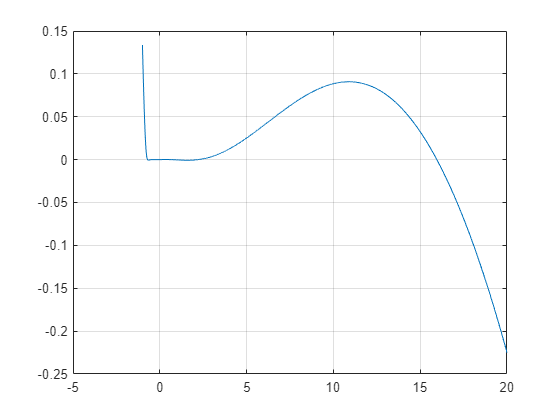

plot(x2,xdif);
grid on

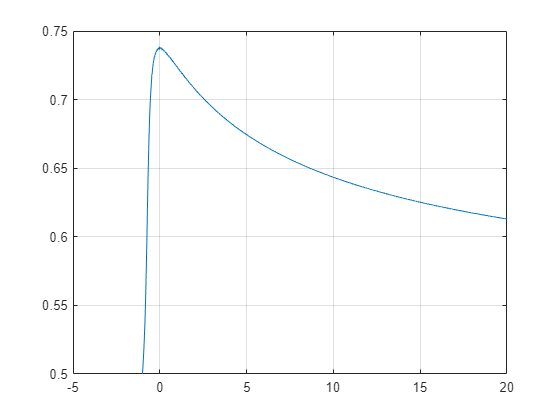

plot(x2,T);
grid on

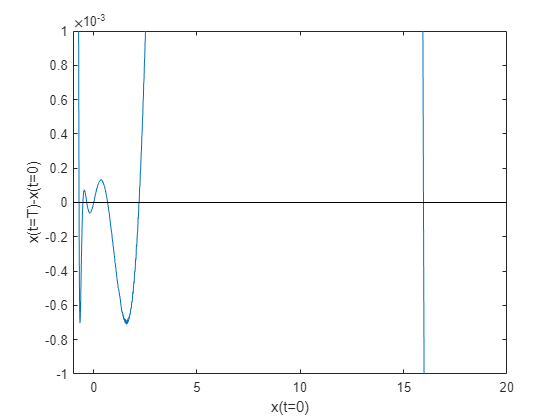

plot(x2,xdif); ylim([-1e-3,1e-3]), xlim([-1 20])
xlabel("x(t=0)"); ylabel("x(t=T)-x(t=0)")
hold on
plot(x2, x2*0,"black")
% plot(x2*0, x2,"black")
hold off

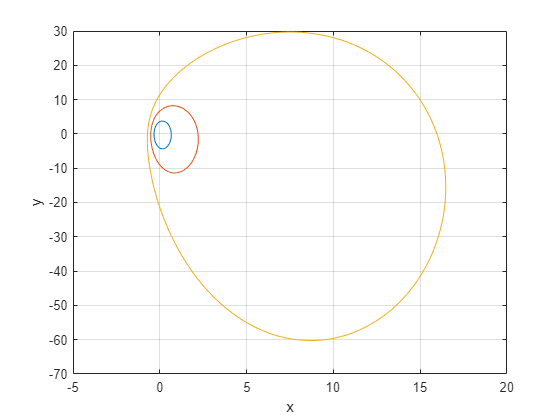

% Starting values of x
values=[0.66 2.2 15.96];

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = ode45cycles(0,x(1),0,0.000000001,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
xlabel("x"); ylabel("y")
hold off

% Starting values of x
values_r=setdiff(-1:0.1:20,0);

x2_r=zeros(size(values_r));
T_r=zeros(size(values_r));
xdif_r=zeros(size(values_r));

for i=1:size(values_r,2)
    x_r=[]; x_r(1) = values_r(i);
    y_r=[]; y_r(1) = 0;
    [T_r(i),x_r,y_r] = ode45cycles_r(0,x_r(1),0,0.000000001,1);
    x2_r(i)=values_r(i);
    z_r = findZero(x_r,y_r);
    xdif_r(i)=z_r(end)-z_r(1);
    plot(x_r,y_r);
    hold on
end
grid on
hold off

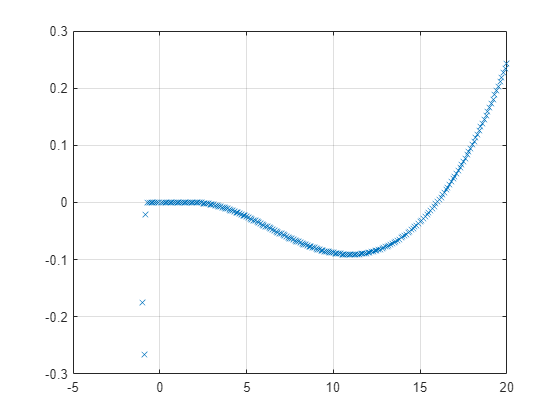

plot(x2_r,xdif_r,"x");
grid on

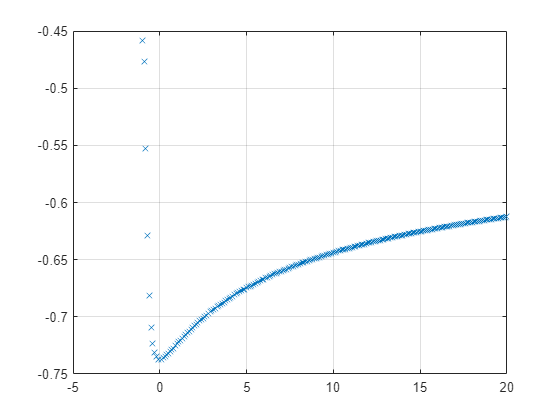

plot(x2_r,T_r,"x");
grid on

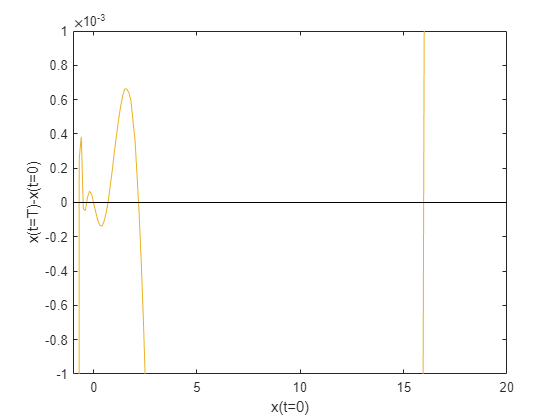

plot(x2_r,xdif_r); ylim([-1e-3,1e-3]), xlim([-1 20])
xlabel("x(t=0)"); ylabel("x(t=T)-x(t=0)")
hold on
plot(x2_r,xdif_r);
plot(x2_r,xdif_r);
plot(x2_r, x2_r*0,"black")
% plot(x2*0, x2,"black")
hold off

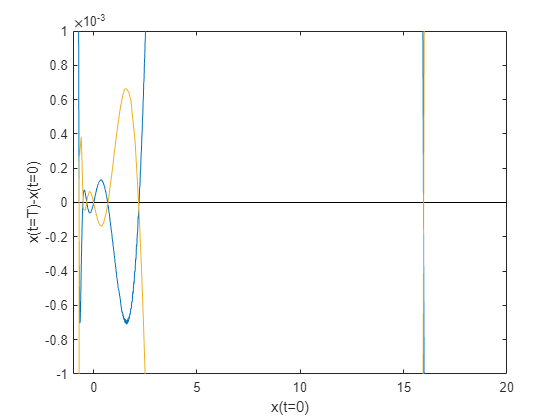

plot(x2,xdif); ylim([-1e-3,1e-3]), xlim([-1 20])
xlabel("x(t=0)"); ylabel("x(t=T)-x(t=0)")
hold on
plot(x2, x2*0,"black")
plot(x2_r,xdif_r); ylim([-1e-3,1e-3]), xlim([-1 20])
hold off

% Starting values of x
values_n=setdiff(-3900:0.5:-3500,0);

x2_n=zeros(size(values_n));
T_n=zeros(size(values_n));
xdif_n=zeros(size(values_n));

for i=1:size(values_n,2)
    x_n=[]; x_n(1) = values_n(i);
    y_n=[]; y_n(1) = 0;
    [T_n(i),x_n,y_n] = ode45cycles(0,x_n(1),y_n(1),0.000000001,1);
    x2_n(i)=values_n(i);
    z_n = findZero(x_n,y_n);
    xdif_n(i)=z_n(end)-z_n(1);
    plot(x_n,y_n);
    hold on
end
grid on
hold off

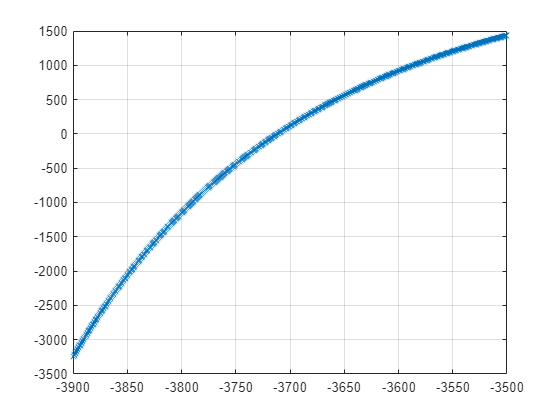

plot(x2_n,xdif_n,"x");
grid on

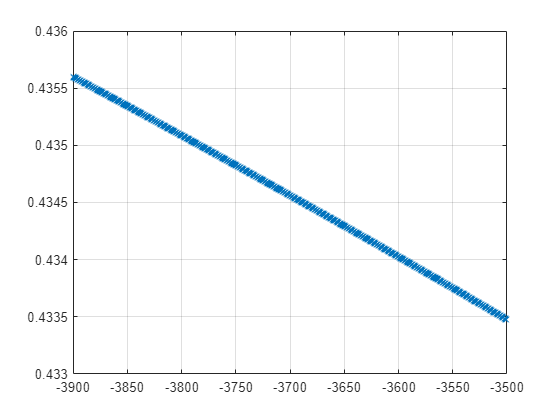

plot(x2_n,T_n,"x");
grid on

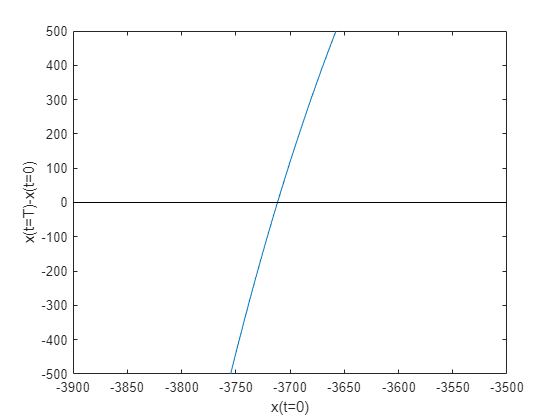

plot(x2_n,xdif_n); ylim([-500 500]), xlim([-3900 -3500])
xlabel("x(t=0)"); ylabel("x(t=T)-x(t=0)")
hold on
plot(x2_n, x2_n*0,"black")
% plot(x2*0, x2,"black")
hold off

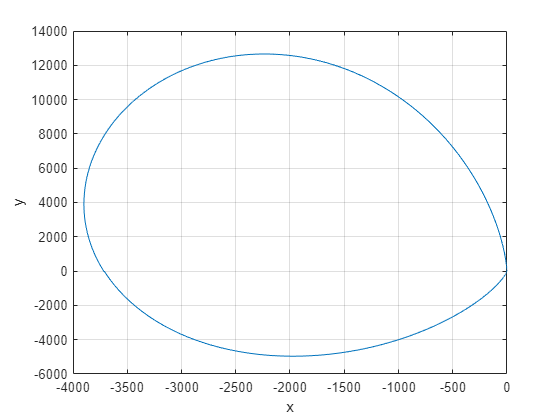

% Starting values of x
values=[-3712];

x2=zeros(size(values));
T=zeros(size(values));
xdif=zeros(size(values));

for i=1:size(values,2)
    x=[]; x(1) = values(i);
    y=[]; y(1) = 0;
    [T(i),x,y] = ode45cycles(0,x(1),0,0.000000001,1);
    x2(i)=values(i);
    z = findZero(x,y);
    xdif(i)=z(end)-z(1);
    plot(x,y);
    hold on
end
grid on
xlabel("x"); ylabel("y")
hold off

function f=fPlotTrajectory(X ,Y, Color1, Color2, Color3)
    lenTr=length(X); lenTr3=round(lenTr /9);
    lenColor1=round(4* lenTr3); lenColor2=round(7* lenTr3);
    
    plot(X(1 : lenColor1), Y(1 : lenColor1), Color1); hold on;
    plot(X(lenColor1 : lenColor2), Y(lenColor1 : lenColor2), Color2);
    hold on;
    plot(X(lenColor2 : length(X)), Y(lenColor2 : length(Y)), Color3);
end

function dz=odefcn(t, z) %
    global a1 b1 c1 al1 bt1 a2 b2 c2 al2 bt2
    dz=zeros(2,1); % z=(z(1) ,z(2))=(x,y)
    
    dz(1)=(a1 * z(1)^2+ b1 * z(1)* z(2)+ c1 * z(2)^2+ al1 * z(1)+ bt1 * z(2));
    dz(2)=(a2 * z(1)^2+ b2 * z(1)* z(2)+ c2 * z(2)^2+ al2 * z(1)+ bt2 * z(2));
end

function [Te,x,y]=ode45cycles(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti+10;
    k=1+2*n;
    [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=2;

    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
        tf=tf+100;
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end

    if(count==cmax)
%         ci=y_sign_change(2)+1;
%         T=T(1:ci);
%         XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
    x=XY(:,1);
    y=XY(:,2);
    Te = T(end);
end

function [Te,x,y]=ode45cycles_r(ti,x0,y0,acc,n)
    options=odeset('RelTol', acc ,'AbsTol', acc, 'InitialStep', acc, 'NormControl','on');
    tf=ti-10;
    k=1+2*n;
    [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
    y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    count=0;cmax=2;

    while size(y_sign_change,1)<k && count<cmax
        count=count+1;
        [T, XY]= ode45(@(T,XY) odefcn(T,XY), [ti tf], [x0 y0], options);
        tf=tf-100;
        y_sign_change = find(XY(1:end-1 ,2).*XY(2:end,2)<=0);
    end

    if(count==cmax)
%         ci=y_sign_change(2)+1;
%         T=T(1:ci);
%         XY=XY(1:ci,:);
    else
        ci=y_sign_change(k)+1;
    
        T=T(1:ci);
        XY=XY(1:ci,:);
    end
    x=XY(:,1);
    y=XY(:,2);
    Te = T(end);
end

function x0 = findZero(x,y)

    zci = @(v) find(v(:).*circshift(v(:), [-1 0]) <= 0);                    % Returns Approximate Zero-Crossing Indices Of Argument Vector
    dy = zci(y);                                                            % Indices of Approximate Zero-Crossings
    for k1 = 1:size(dy,1)-1
        b = [[1;1] [x(dy(k1)); x(dy(k1)+1)]]\[y(dy(k1)); y(dy(k1)+1)];      % Linear Fit Near Zero-Crossings
        x0(k1) = -b(1)/b(2);                                                % Interpolate ‘Exact’ Zero Crossing
        mb(:,k1) = b;                                                       % Store Parameter Estimates (Optional)
    end
end